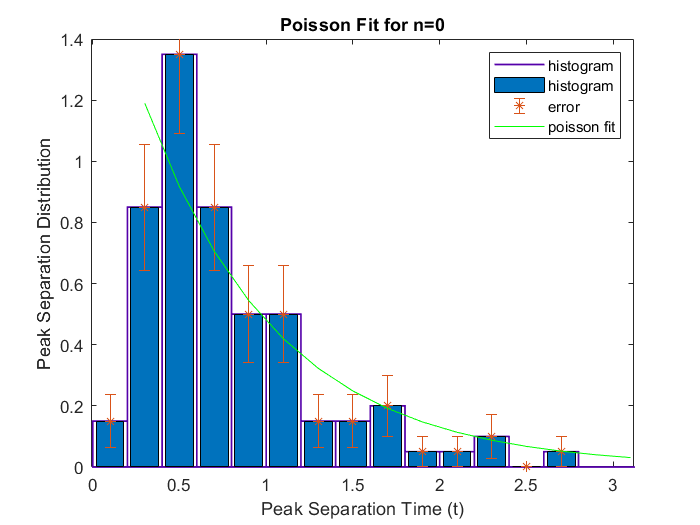

clf;
hold on;
LegHandles = []; LegText = {};

%CREATING THE HISTOGRAM

[CdfF,CdfX] = ecdf(olan0,'Function','cdf'); 
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(olan0,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
box on;
%CREATING ERROR BARS

normalizedelements=[0.15 0.85 1.35 0.85 0.5 0.5 0.15 0.15 0.2 0.05 0.05 0.1 0 0.05];
elements=20*normalizedelements;
bincenters= 0.1:0.2:2.7;
err=sqrt(elements)/20;
bar(bincenters, normalizedelements);

errorbar(bincenters,normalizedelements, err,'*');
%DEFINING POISSON FIT
%Where b=a.c here c is just a  irrelevant constant!
a=1.305;
b=1.76;
exp0=b*exp(-a*pos0b);
plot(pos0b,exp0,'g')


title('Poisson Fit for n=0')
xlabel('Peak Separation Time (t)')
ylabel('Peak Separation Distribution')

xlim([-0.01 3.12])
ylim([0.00 1.40])
legend({'histogram','histogram','error','poisson fit'})


%Coefficients (with 68% confidence bounds):
%       a =       1.305  \mp 0.269
 %      b =        1.76  \mp 0.332

%Goodness of fit:
 % SSE: 0.393
  %R-square: 0.8316
  %Adjusted R-square: 0.8187
 % RMSE: 0.1739
